# Proyecto Global Integrador - Control de PMSM

## Análisis de Linealización (Modelo LTI equivalente aumentado)

clear; clc;

### 1. Validación Simbólica del Polinomio Característico y Funciones de Transferencia

% Definición de variables simbólicas (reales y positivas)
syms s L_q_sym R_s_sym J_eq_sym b_eq_sym K_t_sym K_v_sym r_sym real positive

% Matriz del sistema M(s) obtenida agrupando los estados a la izquierda:
%  1) s*Theta_m - Omega_m = 0
%  2) (J_eq*s + b_eq)*Omega_m - K_t*I_qs = -1/r * T_l
%  3) K_v*Omega_m + (L_q*s + R_s)*I_qs = V_qs

M_s = [ s,                  -1,               0;
        0,     J_eq_sym*s + b_eq_sym,            -K_t_sym;
        0,               K_v_sym,  L_q_sym*s + R_s_sym ];

% Matriz de entrada B_in asociada al vector U(s) = [V_qs; T_l]'
B_in = [   0,    0;
           0, -1/r_sym;
           1,    0 ];

% Calculamos la matriz de transferencia del sistema G_matriz = inv(M_s) * B_in
disp('Matriz de Transferencia Completa del Sistema:')
G_matriz = simplify(M_s \ B_in)

% Aislamiento de las plantas individuales
G_v_raw = G_matriz(1,1); % Canal Tensión -> Posición
G_d_raw = G_matriz(1,2); % Canal Torque -> Posición

disp('Función de Transferencia Principal G_v(s) [V_qs -> Theta_m]:')
G_v = collect(G_v_raw, s)

disp('Función de Transferencia de Perturbación G_d(s) [T_l -> Theta_m]:')
G_d = collect(G_d_raw, s)

% Extracción del Polinomio Característico
[~, Dinominador_Comun] = numden(G_v_raw);
disp('Polinomio Característico del Motor Delta(s):')
Delta_s = collect(Dinominador_Comun, s)

% Separación del polo integrador (s=0)
Delta_em_s = simplify(Delta_s / s);
Delta_em_exp = collect(expand(Delta_em_s), s);

% Extraemos los coeficientes del polinomio de segundo orden (A*s^2 + B*s + C = 0
coeficientes = coeffs(Delta_em_exp, s);
C_sym = coeficientes(1); 
B_sym = coeficientes(2); 
A_sym = coeficientes(3);

% Cálculo simbólico de la frecuencia natural y amortiguamiento
wn_simbolico = sqrt(simplify(C_sym / A_sym));
zeta_simbolico = simplify((B_sym / A_sym) / (2 * wn_simbolico));

disp('--- Parámetros del Modo Electromecánico ---');
disp('Frecuencia natural no amortiguada (\omega_{n,em}):')
wn_em_sym = wn_simbolico
disp('Factor de amortiguamiento (\zeta_{em}):')
zeta_em_sym = zeta_simbolico

### 2. Analisis de Estabilidad a Lazo Abierto del Modelo LTI Aumentado

% Inicializacion del Workspace
run('init_sistema_completo.m')

--------------------------------------------------
Iniciando carga de parámetros del sistema acoplado...
--------------------------------------------------
Cargando: params_subsistema_mecanico.m ...
Cargando: params_subsistema_electromagnetico.m ...
Cargando: params_subsistema_termico.m ...
--------------------------------------------------
¡ÉXITO! Todos los parámetros han sido cargados.
--------------------------------------------------



% Constantes electromagneticas derivadas (asumiendo I_ds = 0)
K_t = (3/2) * Pp * lambda_m;
K_v = Pp * lambda_m;

#### 3.a) Analisis del Caso Nominal (Valores numéricos e Identificación)

% 1. Cálculo de Parámetros Dinámicos Nominales
wn_nom = sqrt((Rs_REF * beq_nom + K_t * K_v) / (Jeq_nom * L_q));
zeta_nom = (L_q * beq_nom + Rs_REF * Jeq_nom) / (2 * sqrt(Jeq_nom * L_q * (Rs_REF * beq_nom + K_t * K_v)));

% 2. Identificación de Autovalores (Polos)
% Modo Integrador (Cinematico)
p1_nom = 0;

% Modos Electromecanicos Conjugados
sigma_nom = zeta_nom * wn_nom;
wd_nom = wn_nom * sqrt(1 - zeta_nom^2);
p23_nom = [-sigma_nom + 1i*wd_nom; -sigma_nom - 1i*wd_nom];

% Modos Residuales Inobservables desde la mecanica
pd_nom = -Rs_REF / L_d;
pT_nom = -1 / (Rts_amb * Cts);

% 3. Identificacion de Ceros
zd_nom = -Rs_REF / L_q;

% --- IMPRESIÓN DE RESULTADOS (Formato Tabla Profesional) ---
disp('================================================================');

disp('   3.a) POLOS, CEROS Y MODOS DE OSCILACIÓN (CASO NOMINAL)       ');

   3.a) POLOS, CEROS Y MODOS DE OSCILACIÓN (CASO NOMINAL)       


disp('================================================================');

fprintf('\n--- 1. Subsistema Cinemático (Integrador) ---\n');


--- 1. Subsistema Cinemático (Integrador) ---


fprintf('Polo p1        = %0.2f\n', p1_nom);

Polo p1        = 0.00


fprintf('Efecto         : Posición libre sin resorte de retorno.\n');

Efecto         : Posición libre sin resorte de retorno.



fprintf('\n--- 2. Subsistema Electromecánico (Dominante) ---\n');


--- 2. Subsistema Electromecánico (Dominante) ---


fprintf('Polos p2,3     = %0.2f ± j%0.2f rad/s\n', real(p23_nom(1)), imag(p23_nom(1)));

Polos p2,3     = -88.49 ± j149.94 rad/s


fprintf('Frec. Natural  : wn_nom = %0.2f rad/s (%0.2f Hz)\n', wn_nom, wn_nom/(2*pi));

Frec. Natural  : wn_nom = 174.10 rad/s (27.71 Hz)


fprintf('Amortiguamiento: zeta   = %0.4f (Subamortiguado)\n', zeta_nom);

Amortiguamiento: zeta   = 0.5082 (Subamortiguado)


fprintf('Cte. de Tiempo : tau_em = %0.4f s (Decaimiento de la envolvente)\n', 1/sigma_nom);

Cte. de Tiempo : tau_em = 0.0113 s (Decaimiento de la envolvente)



fprintf('\n--- 3. Subsistemas Desacoplados (Inobservables desde theta_m) ---\n');


--- 3. Subsistemas Desacoplados (Inobservables desde theta_m) ---


fprintf('Polo eje d (pd) = %0.2f rad/s  --> tau_d = %0.4f s\n', pd_nom, -1/pd_nom);

Polo eje d (pd) = -154.55 rad/s  --> tau_d = 0.0065 s


fprintf('Polo Térm. (pT) = %0.4f rad/s  --> tau_T = %0.2f s\n', pT_nom, -1/pT_nom);

Polo Térm. (pT) = -0.0083 rad/s  --> tau_T = 120.00 s



fprintf('\n--- 4. Ceros de Transmisión ---\n');


--- 4. Ceros de Transmisión ---


fprintf('Cero Perturb.  : z_d = %0.2f rad/s\n', zd_nom);

Cero Perturb.  : z_d = -175.86 rad/s


fprintf('Efecto         : Adelanto de fase local ante torque de carga.\n');

Efecto         : Adelanto de fase local ante torque de carga.


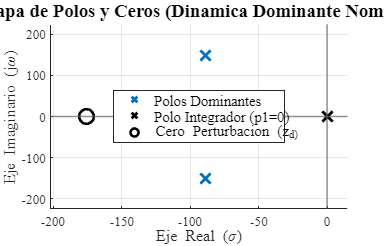

SignalPlotter: Figura exportada exitosamente en: docs\img\mapa_pz_nominal.pdf



% Instanciamos la clase gráfica profesional
plotter_nom = SignalPlotter("docs/img/");

polesList_nom = {p23_nom};
[fig_pz, ax_pz] = plotter_nom.plotPoleSweep(polesList_nom, 100, '', ...
    'Title', 'Mapa de Polos y Ceros (Dinamica Dominante Nominal)');

hold(ax_pz, 'on');

% Polo en el Origen
scatter(ax_pz, 0, 0, 120, 'x', 'MarkerEdgeColor', 'k', 'LineWidth', 2, ...
    'DisplayName', 'Polo Integrador (p1=0)');

% Cero de Perturbacion
scatter(ax_pz, real(zd_nom), imag(zd_nom), 120, 'o', 'MarkerEdgeColor', 'k', 'LineWidth', 2, ...
    'DisplayName', 'Cero Perturbacion (z_d)');

% Llamamos a la leyenda al final
legend(ax_pz, 'Location', 'best', 'FontName', plotter_nom.FontFamily, 'FontSize', plotter_nom.FontSizeLegend);

% --- AJUSTES DE ENCUADRE DINÁMICO ---
% Límite Y: Mantiene la proporción respecto a la frecuencia amortiguada
ylim(ax_pz, [-(wd_nom*1.5), (wd_nom*1.5)]); 

% Límite X: Busca el valor más negativo (el cero o los polos) y le da 15% de margen
limite_izq = min([real(p23_nom(1)), zd_nom]) * 1.15; 
limite_der = 15; % Margen fijo a la derecha para que el polo en el origen no quede pegado al borde

xlim(ax_pz, [limite_izq, limite_der]);   

hold(ax_pz, 'off');

% Exportación
plotter_nom.export(fig_pz, 'mapa_pz_nominal.pdf');

#### 3.b.1) Migración de Polos: Variación de masa de Carga Útil (m_l)

disp('--- Análisis de Sensibilidad: Masa de Carga (m_l) ---');

--- Análisis de Sensibilidad: Masa de Carga (m_l) ---



num_steps = 15; % Mayor resolución para ver la curva suave
ml_sweep = linspace(ml_min, ml_max, num_steps);

% Inicialización de celdas y vectores
polesList_ml = cell(num_steps, 1);
wn_ml_array = zeros(num_steps, 1);
zeta_ml_array = zeros(num_steps, 1);

for i = 1:num_steps
    % 1. Extraemos parámetro actual
    ml_i = ml_sweep(i);
    
    % 2. Propagación hacia Inercia Equivalente (Jeq)
    Jl_i = (m*Lcm^2 + Jcm) + ml_i*Ll^2;
    Jeq_i = Jm + Jl_i/r^2;
    
    % Mantenemos fricción y resistencia nominales
    beq_i = beq_nom;
    Rs_i = Rs_REF;
    
    % 3. Cálculo de la dinámica dominante
    wn_i   = sqrt((Rs_i * beq_i + K_t * K_v) / (Jeq_i * L_q));
    zeta_i = (L_q * beq_i + Rs_i * Jeq_i) / ...
             (2 * sqrt(Jeq_i * L_q * (Rs_i * beq_i + K_t * K_v)));
    
    sigma_i = zeta_i * wn_i;
    wd_i    = wn_i * sqrt(1 - zeta_i^2);
    
    % 4. Almacenamiento
    polesList_ml{i} = [-sigma_i + 1i*wd_i; -sigma_i - 1i*wd_i];
    wn_ml_array(i) = wn_i;
    zeta_ml_array(i) = zeta_i;
end

% --- RESULTADOS EXTREMOS EN CONSOLA ---
idx_mid = ceil(num_steps / 2);
fprintf('Condición Mínima (m_l = %.2f kg): wn = %6.2f rad/s, zeta = %.4f\n', ml_sweep(1), wn_ml_array(1), zeta_ml_array(1));

Condición Mínima (m_l = 0.00 kg): wn = 174.10 rad/s, zeta = 0.5082


fprintf('Condición Media  (m_l = %.2f kg): wn = %6.2f rad/s, zeta = %.4f\n', ml_sweep(idx_mid), wn_ml_array(idx_mid), zeta_ml_array(idx_mid));

Condición Media  (m_l = 0.75 kg): wn = 135.21 rad/s, zeta = 0.6528


fprintf('Condición Máxima (m_l = %.2f kg): wn = %6.2f rad/s, zeta = %.4f\n', ml_sweep(end), wn_ml_array(end), zeta_ml_array(end));

Condición Máxima (m_l = 1.50 kg): wn = 114.40 rad/s, zeta = 0.7707


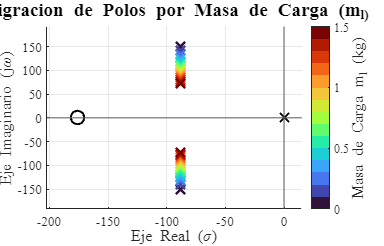

SignalPlotter: Figura exportada exitosamente en: docs\img\mapa_pz_migracion_ml.pdf



% =========================================================================
% --- DIAGRAMA DE LUGAR DE RAÍCES: VARIACIÓN m_l ---
% =========================================================================
plotter_ml = SignalPlotter("docs/img/");
etiqueta_colorbar_ml = 'Masa de Carga m_{l} (kg)'; 

[fig_ml, ax_ml] = plotter_ml.plotPoleSweep(...
    polesList_ml, ...
    ml_sweep, ...
    etiqueta_colorbar_ml, ...
    'Title', 'Migracion de Polos por Masa de Carga (m_l)');

hold(ax_ml, 'on');

% Marcadores de Referencia Fijos
scatter(ax_ml, p1_nom, 0, 100, 'x', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');
scatter(ax_ml, real(zd_nom), imag(zd_nom), 100, 'o', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');

% Ajuste de límites estandarizado
xlim_min_sweep = min([real(polesList_ml{1}(1)), zd_nom]) * 1.15;
xlim(ax_ml, [xlim_min_sweep, 15]);
ylim(ax_ml, [-(wn_ml_array(1) * 1.1), (wn_ml_array(1) * 1.1)]);   

hold(ax_ml, 'off');

plotter_ml.export(fig_ml, 'mapa_pz_migracion_ml.pdf');

#### 3.b.2) Migracion de Polos: Variacion de Friccion Viscosa

%% ========================================================================
% 3.b.2) MIGRACIÓN DE POLOS: VARIACIÓN DE FRICCIÓN VISCOSA (b_l)
% =========================================================================
disp('--- Análisis de Sensibilidad: Fricción Viscosa de Carga (b_l) ---');

--- Análisis de Sensibilidad: Fricción Viscosa de Carga (b_l) ---



num_steps = 15; 
bl_sweep = linspace(bl_min, bl_max, num_steps);

polesList_bl = cell(num_steps, 1);
wn_bl_array = zeros(num_steps, 1);
zeta_bl_array = zeros(num_steps, 1);

for i = 1:num_steps
    % 1. Extraemos parámetro actual
    bl_i = bl_sweep(i);
    
    % 2. Propagación hacia Fricción Equivalente (beq)
    beq_i = bm + bl_i/r^2;
    
    % Mantenemos inercia y resistencia nominales
    Jeq_i = Jeq_nom;
    Rs_i = Rs_REF;
    
    % 3. Cálculo de la dinámica dominante
    wn_i   = sqrt((Rs_i * beq_i + K_t * K_v) / (Jeq_i * L_q));
    zeta_i = (L_q * beq_i + Rs_i * Jeq_i) / ...
             (2 * sqrt(Jeq_i * L_q * (Rs_i * beq_i + K_t * K_v)));
    
    sigma_i = zeta_i * wn_i;
    wd_i    = wn_i * sqrt(1 - zeta_i^2);
    
    % 4. Almacenamiento
    polesList_bl{i} = [-sigma_i + 1i*wd_i; -sigma_i - 1i*wd_i];
    wn_bl_array(i) = wn_i;
    zeta_bl_array(i) = zeta_i;
end

% --- RESULTADOS EN CONSOLA (Mínimo, Nominal, Máximo) ---
idx_mid = ceil(num_steps / 2);
fprintf('Condición Mínima  (b_l = %5.3f): wn = %6.2f rad/s, zeta = %.4f\n', bl_sweep(1), wn_bl_array(1), zeta_bl_array(1));

Condición Mínima  (b_l = 0.070): wn = 174.05 rad/s, zeta = 0.5081


fprintf('Condición Nominal (b_l = %5.3f): wn = %6.2f rad/s, zeta = %.4f\n', bl_sweep(idx_mid), wn_bl_array(idx_mid), zeta_bl_array(idx_mid));

Condición Nominal (b_l = 0.100): wn = 174.10 rad/s, zeta = 0.5082


fprintf('Condición Máxima  (b_l = %5.3f): wn = %6.2f rad/s, zeta = %.4f\n', bl_sweep(end), wn_bl_array(end), zeta_bl_array(end));

Condición Máxima  (b_l = 0.130): wn = 174.16 rad/s, zeta = 0.5084


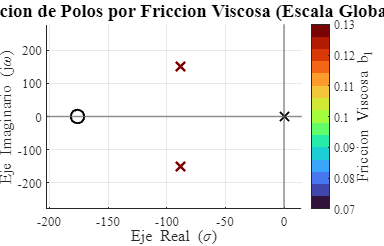

SignalPlotter: Figura exportada exitosamente en: docs\img\mapa_pz_migracion_bl_global.pdf



% =========================================================================
% --- DIAGRAMA 1: ESCALA GLOBAL (Consistencia visual) ---
% =========================================================================
plotter_bl = SignalPlotter("docs/img/");
etiqueta_colorbar_bl = 'Friccion Viscosa b_l'; 

[fig_bl_global, ax_bl_global] = plotter_bl.plotPoleSweep(...
    polesList_bl, bl_sweep, etiqueta_colorbar_bl, ...
    'Title', 'Migracion de Polos por Friccion Viscosa (Escala Global)');

hold(ax_bl_global, 'on');
scatter(ax_bl_global, p1_nom, 0, 100, 'x', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');
scatter(ax_bl_global, real(zd_nom), imag(zd_nom), 100, 'o', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');

% Misma escala que en m_l
xlim(ax_bl_global, [xlim_min_sweep, 15]);
ylim(ax_bl_global, [-(wn_nom * 1.6), (wn_nom * 1.6)]);   
hold(ax_bl_global, 'off');

% =========================================================================
% --- DIAGRAMA 2: ZOOM EN EL POLO SUPERIOR ---
% =========================================================================
% Extraemos solo la parte real e imaginaria del polo superior (índice 1)
partes_reales = cellfun(@(p) real(p(1)), polesList_bl);
partes_imags  = cellfun(@(p) imag(p(1)), polesList_bl);

% Calculamos márgenes ajustados (10% de la máxima variación)
margen_real = abs(max(partes_reales) - min(partes_reales)) * 0.15;
margen_imag = abs(max(partes_imags) - min(partes_imags)) * 0.15;
if margen_real == 0, margen_real = 0.01; end % Evita errores si el polo no se mueve en absoluto
if margen_imag == 0, margen_imag = 0.01; end

[fig_bl_zoom, ax_bl_zoom] = plotter_bl.plotPoleSweep(...
    polesList_bl, bl_sweep, etiqueta_colorbar_bl, ...
    'Title', 'Migracion de Polos por Friccion Viscosa (Detalle)');

% Aplicamos el encuadre milimétrico sobre la trayectoria del polo
xlim(ax_bl_zoom, [min(partes_reales) - margen_real, max(partes_reales) + margen_real]);
ylim(ax_bl_zoom, [min(partes_imags) - margen_imag, max(partes_imags) + margen_imag]);


plotter_bl.export(fig_bl_global, 'mapa_pz_migracion_bl_global.pdf');

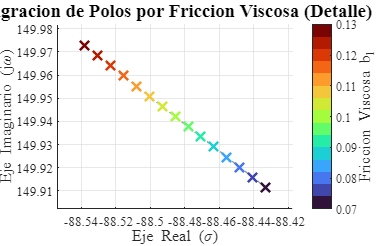

SignalPlotter: Figura exportada exitosamente en: docs\img\mapa_pz_migracion_bl_zoom.pdf


plotter_bl.export(fig_bl_zoom, 'mapa_pz_migracion_bl_zoom.pdf');

%% ========================================================================
% 3.b.3) MIGRACIÓN DE POLOS Y CEROS: VARIACIÓN TÉRMICA DE ESTATOR (T_s)
% =========================================================================
disp('--- Análisis de Sensibilidad: Temperatura del Estator (T_s) ---');

--- Análisis de Sensibilidad: Temperatura del Estator (T_s) ---



% Rango de variación térmica
Ts_min = Ts_REF;         % 20 °C (Motor en frío)
Ts_max = 115.0;          % 115 °C (Límite operativo máximo)

num_steps = 15; 
Ts_sweep = linspace(Ts_min, Ts_max, num_steps);

polesList_Ts  = cell(num_steps, 1);
zd_Ts_array   = zeros(num_steps, 1);
wn_Ts_array   = zeros(num_steps, 1);
zeta_Ts_array = zeros(num_steps, 1);

for i = 1:num_steps
    % 1. Extraemos parámetro térmico actual
    Ts_i = Ts_sweep(i);
    
    % 2. Propagación hacia Resistencia de Estator (Rs)
    Rs_i = Rs_REF * (1 + alpha_Cu * (Ts_i - Ts_REF));
    
    % Mantenemos inercia y fricción nominales
    Jeq_i = Jeq_nom;
    beq_i = beq_nom;
    
    % 3. Cálculo de la dinámica dominante
    wn_i   = sqrt((Rs_i * beq_i + K_t * K_v) / (Jeq_i * L_q));
    zeta_i = (L_q * beq_i + Rs_i * Jeq_i) / ...
             (2 * sqrt(Jeq_i * L_q * (Rs_i * beq_i + K_t * K_v)));
    
    sigma_i = zeta_i * wn_i;
    wd_i    = wn_i * sqrt(1 - zeta_i^2);
    
    % 4. Almacenamiento de Polos y Cero
    polesList_Ts{i} = [-sigma_i + 1i*wd_i; -sigma_i - 1i*wd_i];
    zd_Ts_array(i)  = -Rs_i / L_q; % El cero migra con la temperatura
    
    wn_Ts_array(i)   = wn_i;
    zeta_Ts_array(i) = zeta_i;
end

% --- RESULTADOS EN CONSOLA (Mínimo, Nominal, Máximo) ---
idx_mid = ceil(num_steps / 2);
fprintf('Condición Mínima  (T_s = %5.1f °C): wn = %6.2f rad/s, zeta = %.4f, zd = %6.1f rad/s\n', Ts_sweep(1), wn_Ts_array(1), zeta_Ts_array(1), zd_Ts_array(1));

Condición Mínima  (T_s =  20.0 °C): wn = 174.10 rad/s, zeta = 0.5082, zd = -175.9 rad/s


fprintf('Condición Media   (T_s = %5.1f °C): wn = %6.2f rad/s, zeta = %.4f, zd = %6.1f rad/s\n', Ts_sweep(idx_mid), wn_Ts_array(idx_mid), zeta_Ts_array(idx_mid), zd_Ts_array(idx_mid));

Condición Media   (T_s =  67.5 °C): wn = 174.21 rad/s, zeta = 0.6014, zd = -208.4 rad/s


fprintf('Condición Máxima  (T_s = %5.1f °C): wn = %6.2f rad/s, zeta = %.4f, zd = %6.1f rad/s\n', Ts_sweep(end), wn_Ts_array(end), zeta_Ts_array(end), zd_Ts_array(end));

Condición Máxima  (T_s = 115.0 °C): wn = 174.31 rad/s, zeta = 0.6945, zd = -241.0 rad/s


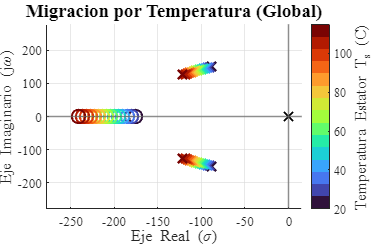

SignalPlotter: Figura exportada exitosamente en: docs\img\mapa_pz_migracion_Ts_global.pdf



% =========================================================================
% --- DIAGRAMA 1: ESCALA GLOBAL (Visualización de Polos y Ceros) ---
% =========================================================================
plotter_Ts = SignalPlotter("docs/img/");
etiqueta_colorbar_Ts = 'Temperatura Estator T_s (C)'; 

[fig_Ts_global, ax_Ts_global] = plotter_Ts.plotPoleSweep(...
    polesList_Ts, Ts_sweep, etiqueta_colorbar_Ts, ...
    'Title', 'Migracion por Temperatura (Global)');

hold(ax_Ts_global, 'on');

% Agregamos el integrador fijo
scatter(ax_Ts_global, p1_nom, 0, 100, 'x', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5, 'HandleVisibility', 'off');

% Dibujamos la migración del Cero (z_d) manualmente con el mismo colormap
colores_Ts = turbo(num_steps);

% Trayectoria del cero
plot(ax_Ts_global, zd_Ts_array, zeros(num_steps, 1), '--', 'Color', [0.6 0.6 0.6], 'LineWidth', 1, 'HandleVisibility', 'off');

% Puntos del cero variando color
for i = 1:num_steps
    scatter(ax_Ts_global, zd_Ts_array(i), 0, 100, 'o', 'MarkerEdgeColor', colores_Ts(i, :), 'LineWidth', 1.5, 'HandleVisibility', 'off');
end

% Ajuste de límites dinámico (El cero se mueve mucho hacia la izquierda)
xlim_min_sweep_Ts = min(zd_Ts_array) * 1.15;
xlim(ax_Ts_global, [xlim_min_sweep_Ts, 15]);
ylim(ax_Ts_global, [-(wn_nom * 1.6), (wn_nom * 1.6)]);   
hold(ax_Ts_global, 'off');

% =========================================================================
% --- DIAGRAMA 2: ZOOM EN EL POLO SUPERIOR ---
% =========================================================================
partes_reales_Ts = cellfun(@(p) real(p(1)), polesList_Ts);
partes_imags_Ts  = cellfun(@(p) imag(p(1)), polesList_Ts);

margen_real_Ts = abs(max(partes_reales_Ts) - min(partes_reales_Ts)) * 0.15;
margen_imag_Ts = abs(max(partes_imags_Ts) - min(partes_imags_Ts)) * 0.15;
if margen_real_Ts == 0, margen_real_Ts = 0.01; end 
if margen_imag_Ts == 0, margen_imag_Ts = 0.01; end

[fig_Ts_zoom, ax_Ts_zoom] = plotter_Ts.plotPoleSweep(...
    polesList_Ts, Ts_sweep, etiqueta_colorbar_Ts, ...
    'Title', 'Migracion por Temperatura (Detalle)');

xlim(ax_Ts_zoom, [min(partes_reales_Ts) - margen_real_Ts, max(partes_reales_Ts) + margen_real_Ts]);
ylim(ax_Ts_zoom, [min(partes_imags_Ts) - margen_imag_Ts, max(partes_imags_Ts) + margen_imag_Ts]);

plotter_Ts.export(fig_Ts_global, 'mapa_pz_migracion_Ts_global.pdf');

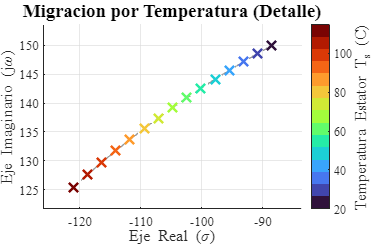

SignalPlotter: Figura exportada exitosamente en: docs\img\mapa_pz_migracion_Ts_zoom.pdf


plotter_Ts.export(fig_Ts_zoom, 'mapa_pz_migracion_Ts_zoom.pdf');

%% ========================================================================
% 4. ANÁLISIS DE OBSERVABILIDAD COMPLETA DE ESTADO
% =========================================================================

% --- 4.1 DEFINICIÓN DEL SISTEMA SIMBÓLICO ALGEBRAICO ---
syms beta_m gamma_m nu_e alpha_q alpha_d alpha_T real positive

% Matriz de Estado (A_LTI)
A_sym = [ 0,         1,        0,         0,         0;
          0,   -beta_m,  gamma_m,         0,         0;
          0,     -nu_e, -alpha_q,         0,         0;
          0,         0,        0,  -alpha_d,         0;
          0,         0,        0,         0,  -alpha_T ];

disp('Matriz de Estado A_LTI (Simbólica):')

Matriz de Estado A_LTI (Simbólica):


A_sym

$$A\_sym = \left(\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & -\beta_{m} & \gamma_{m} & 0 & 0\\ 0 & -\nu_{e} & -\alpha_{q} & 0 & 0\\ 0 & 0 & 0 & -\alpha_{d} & 0\\ 0 & 0 & 0 & 0 & -\alpha_{T} \end{array}\right)$$


%% --- 4.a) Observabilidad utilizando Encoder (Posición theta_m) ---
% Matriz de salida extrayendo el primer estado
C_theta = [1, 0, 0, 0, 0];

% Construcción de la Matriz de Observabilidad
% O = [C; CA; CA^2; CA^3; CA^4]
O_theta_sym = [ C_theta;
                C_theta * A_sym;
                C_theta * A_sym^2;
                C_theta * A_sym^3;
                C_theta * A_sym^4 ];


disp('Matriz de Observabilidad O_theta (Simbólica):')

Matriz de Observabilidad O_theta (Simbólica):


O_theta_sym_simplificada = simplify(O_theta_sym)

$$O\_theta\_sym\_simplificada = \left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0\\ 0 & -\beta_{m} & \gamma_{m} & 0 & 0\\ 0 & {\beta_{m}}^{2}-\gamma_{m}\,\nu_{e} & -\gamma_{m}\,\left(\alpha_{q}+\beta_{m}\right) & 0 & 0\\ 0 & -{\beta_{m}}^{3}+2\,\gamma_{m}\,\nu_{e}\,\beta_{m}+\alpha_{q}\,\gamma_{m}\,\nu_{e} & \beta_{m}\,\left(\alpha_{q}\,\gamma_{m}+\beta_{m}\,\gamma_{m}\right)-\gamma_{m}\,\left(\gamma_{m}\,\nu_{e}-{\alpha_{q}}^{2}\right) & 0 & 0 \end{array}\right)$$


% Cálculo del Rango y Espacio Nulo (Estados ocultos)
rango_theta = rank(O_theta_sym_simplificada);
nulo_theta  = null(O_theta_sym_simplificada);

disp('======================================================');

fprintf('RESULTADOS CASO A (Encoder - Posición):\n');

RESULTADOS CASO A (Encoder - Posición):


fprintf('-> Rango de O_theta: %d (Faltan %d dimensiones)\n', double(rango_theta), 5 - double(rango_theta));

-> Rango de O_theta: 3 (Faltan 2 dimensiones)


disp('-> Base del Espacio Nulo (Vectores inobservables):');

-> Base del Espacio Nulo (Vectores inobservables):


disp(nulo_theta)

$$\left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0\\ 1 & 0\\ 0 & 1 \end{array}\right)$$

disp('Interpretación: Los estados x4 (i_ds) y x5 (T_s) son inobservables.');

Interpretación: Los estados x4 (i_ds) y x5 (T_s) son inobservables.


disp('======================================================');

%% --- 4.b) Observabilidad utilizando Tacogenerador (Velocidad omega_m) ---
% Matriz de salida extrayendo el segundo estado
C_omega = [0, 1, 0, 0, 0];

% Construcción MANUAL de la Matriz de Observabilidad Simbólica
O_omega_sym = [ C_omega;
                C_omega * A_sym;
                C_omega * A_sym^2;
                C_omega * A_sym^3;
                C_omega * A_sym^4 ];

disp('Matriz de Observabilidad O_omega (Simbólica):')

Matriz de Observabilidad O_omega (Simbólica):


O_omega_sym_simplificada = simplify(O_omega_sym)

$$O\_omega\_sym\_simplificada = \begin{array}{l} \left(\begin{array}{ccccc} 0 & 1 & 0 & 0 & 0\\ 0 & -\beta_{m} & \gamma_{m} & 0 & 0\\ 0 & {\beta_{m}}^{2}-\gamma_{m}\,\nu_{e} & -\gamma_{m}\,\left(\alpha_{q}+\beta_{m}\right) & 0 & 0\\ 0 & -{\beta_{m}}^{3}+2\,\gamma_{m}\,\nu_{e}\,\beta_{m}+\alpha_{q}\,\gamma_{m}\,\nu_{e} & \beta_{m}\,\sigma_{1}-\gamma_{m}\,\left(\gamma_{m}\,\nu_{e}-{\alpha_{q}}^{2}\right) & 0 & 0\\ 0 & {\left(\gamma_{m}\,\nu_{e}-{\beta_{m}}^{2}\right)}^{2}-\sigma_{1}\,\left(\alpha_{q}\,\nu_{e}+\beta_{m}\,\nu_{e}\right) & -\gamma_{m}\,\left(\alpha_{q}+\beta_{m}\right)\,\left({\alpha_{q}}^{2}+{\beta_{m}}^{2}-2\,\gamma_{m}\,\nu_{e}\right) & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\alpha_{q}\,\gamma_{m}+\beta_{m}\,\gamma_{m} \end{array}$$


% Cálculo del Rango y Espacio Nulo (Estados ocultos)
rango_omega = rank(O_omega_sym_simplificada);
nulo_omega  = null(O_omega_sym_simplificada);

disp('======================================================');

fprintf('RESULTADOS CASO B (Tacogenerador - Velocidad):\n');

RESULTADOS CASO B (Tacogenerador - Velocidad):


fprintf('-> Rango de O_omega: %d (Faltan %d dimensiones)\n', double(rango_omega), 5 - double(rango_omega));

-> Rango de O_omega: 2 (Faltan 3 dimensiones)


disp('-> Base del Espacio Nulo (Vectores inobservables):');

-> Base del Espacio Nulo (Vectores inobservables):


disp(nulo_omega)

$$\left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

disp('Interpretación: Los estados x1 (theta_m), x4 (i_ds) y x5 (T_s) son inobservables.');

Interpretación: Los estados x1 (theta_m), x4 (i_ds) y x5 (T_s) son inobservables.


disp('======================================================');


%% --- 4.2 VALIDACIÓN NUMÉRICA ---
% OJO: Aquí SÍ podemos usar la función obsv() porque le pasaremos números reales (double)

A_num = [ 0, 1, 0, 0, 0;
          0, -beq_nom/Jeq_nom, K_t/Jeq_nom, 0, 0;
          0, -K_v/L_q, -Rs_REF/L_q, 0, 0;
          0, 0, 0, -Rs_REF/L_d, 0;
          0, 0, 0, 0, -1/(Rts_amb*Cts) ];

O_theta_num = obsv(A_num, C_theta);
O_omega_num = obsv(A_num, C_omega);

% Calculamos la inobservabilidad numérica
estados_ocultos_pos = length(A_num) - rank(O_theta_num);
estados_ocultos_vel = length(A_num) - rank(O_omega_num);

fprintf('\n=== VALIDACIÓN NUMÉRICA NOMINAL ===\n');


=== VALIDACIÓN NUMÉRICA NOMINAL ===


fprintf('Midiendo Posición : Estados inobservables = %d\n', estados_ocultos_pos);

Midiendo Posición : Estados inobservables = 2


fprintf('Midiendo Velocidad: Estados inobservables = %d\n', estados_ocultos_vel);

Midiendo Velocidad: Estados inobservables = 3


if estados_ocultos_pos == 2 && estados_ocultos_vel == 3
    disp('ÉXITO: La validación numérica corrobora perfectamente el desarrollo analítico.');
end

ÉXITO: La validación numérica corrobora perfectamente el desarrollo analítico.
